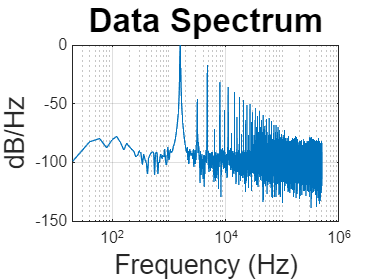

@Freq = 1586.910, SNR = 33.553 dB, SNDR = 17.653 dB, SFDR = 17.953 dB, HD2 = 46.449 and HD3 = 17.953


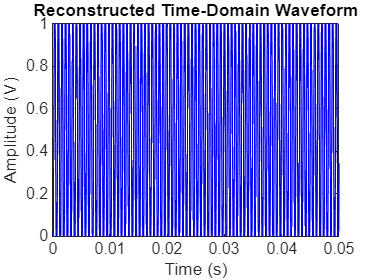

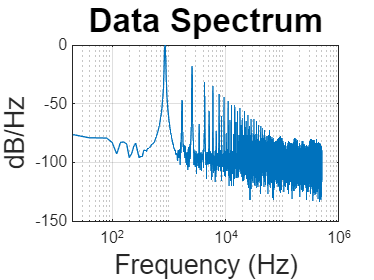

@Freq = 854.490, SNR = 33.541 dB, SNDR = 17.641 dB, SFDR = 17.941 dB, HD2 = 46.239 and HD3 = 17.941


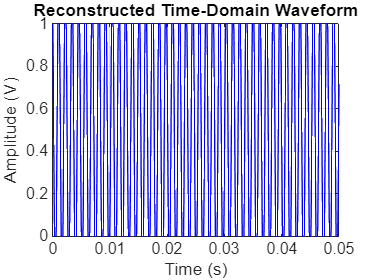

@Freq = 854.490, SNR = 33.541 dB, SNDR = 17.641 dB, SFDR = 17.941 dB, HD2 = 46.239 and HD3 = 17.941


@Freq = 1586.910, SNR = 33.553 dB, SNDR = 17.653 dB, SFDR = 17.953 dB, HD2 = 46.449 and HD3 = 17.953


@Freq = 1586.910, SNR = 33.553 dB, SNDR = 17.653 dB, SFDR = 17.953 dB, HD2 = 46.449 and HD3 = 17.953


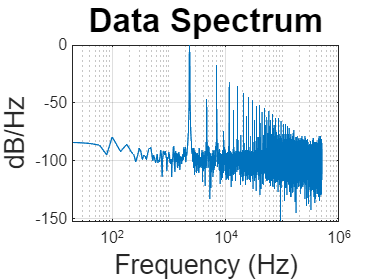

@Freq = 2319.340, SNR = 33.546 dB, SNDR = 17.654 dB, SFDR = 17.956 dB, HD2 = 46.657 and HD3 = 17.956


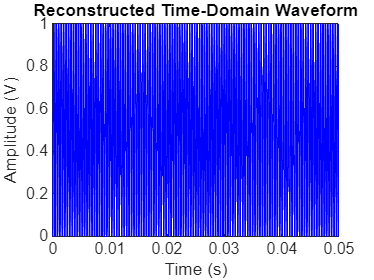

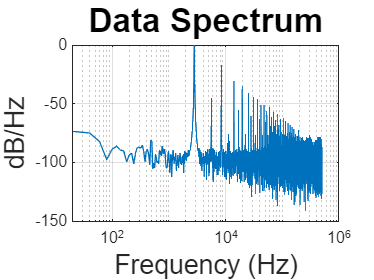

@Freq = 2807.620, SNR = 33.537 dB, SNDR = 17.654 dB, SFDR = 17.957 dB, HD2 = 46.279 and HD3 = 17.957


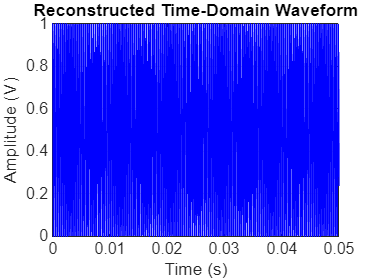

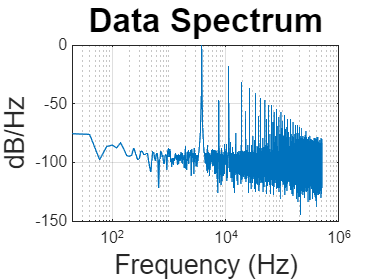

@Freq = 3784.180, SNR = 33.538 dB, SNDR = 17.652 dB, SFDR = 17.955 dB, HD2 = 46.221 and HD3 = 17.955


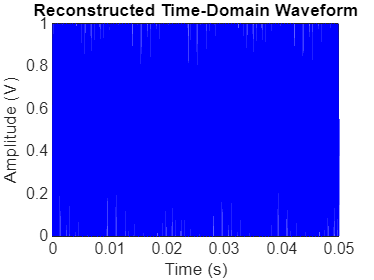

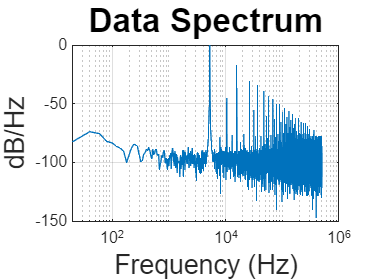

@Freq = 5249.020, SNR = 33.545 dB, SNDR = 17.656 dB, SFDR = 17.958 dB, HD2 = 46.372 and HD3 = 17.958


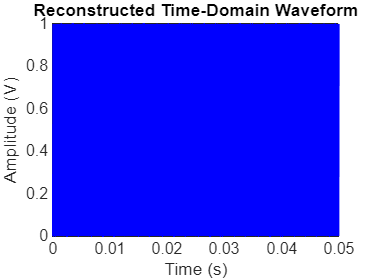

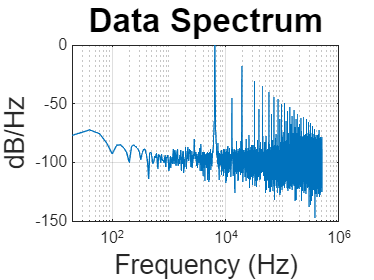

@Freq = 6469.730, SNR = 33.546 dB, SNDR = 17.657 dB, SFDR = 17.959 dB, HD2 = 46.247 and HD3 = 17.959


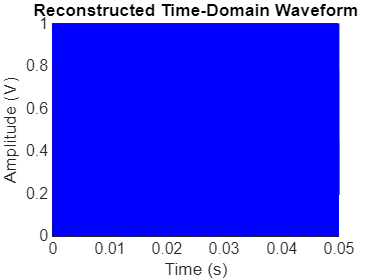

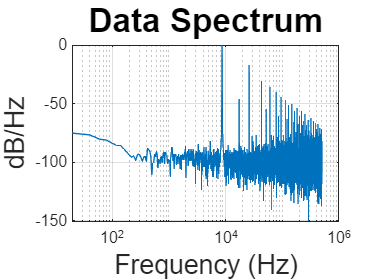

@Freq = 8666.990, SNR = 33.548 dB, SNDR = 17.658 dB, SFDR = 17.961 dB, HD2 = 46.155 and HD3 = 17.961


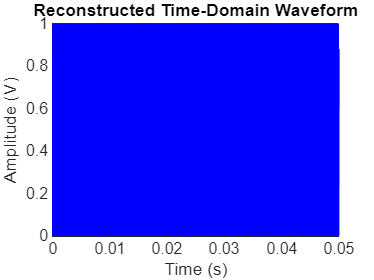

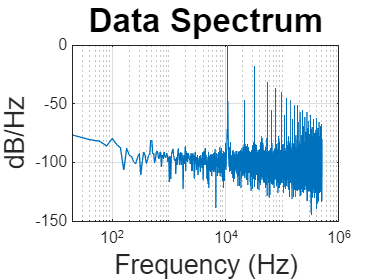

@Freq = 10864.260, SNR = 33.549 dB, SNDR = 17.656 dB, SFDR = 17.959 dB, HD2 = 45.904 and HD3 = 17.959


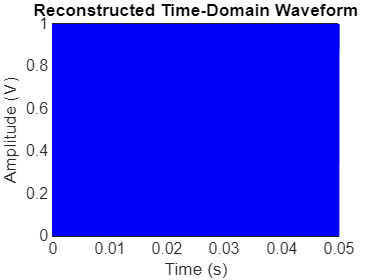

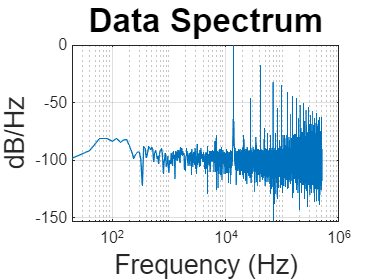

@Freq = 13793.950, SNR = 33.529 dB, SNDR = 17.650 dB, SFDR = 17.953 dB, HD2 = 46.082 and HD3 = 17.953


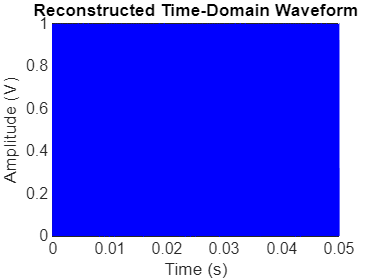

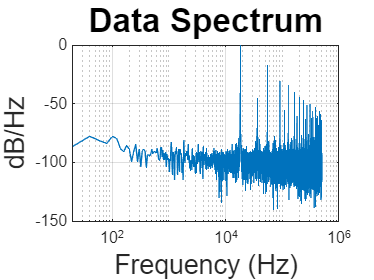

@Freq = 18188.480, SNR = 33.532 dB, SNDR = 17.653 dB, SFDR = 17.955 dB, HD2 = 46.378 and HD3 = 17.955


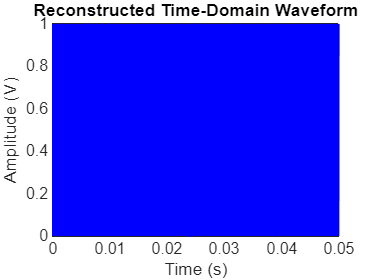

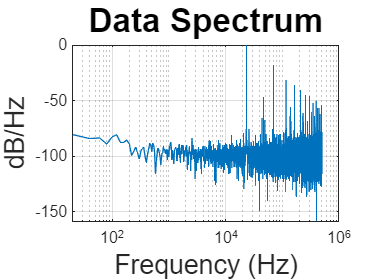

@Freq = 23315.430, SNR = 33.532 dB, SNDR = 17.650 dB, SFDR = 17.952 dB, HD2 = 46.350 and HD3 = 17.952


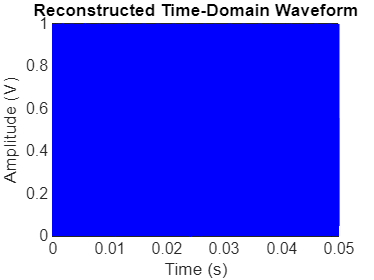

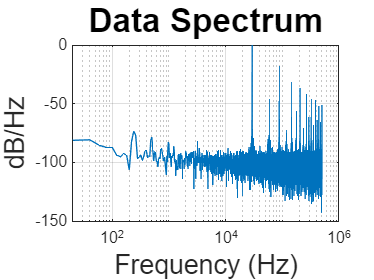

@Freq = 29418.950, SNR = 33.529 dB, SNDR = 17.650 dB, SFDR = 17.952 dB, HD2 = 45.903 and HD3 = 17.952


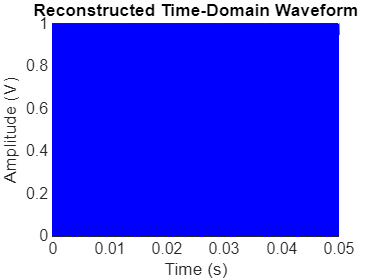

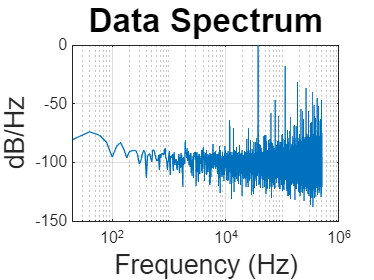

@Freq = 37475.590, SNR = 33.529 dB, SNDR = 17.649 dB, SFDR = 17.951 dB, HD2 = 46.246 and HD3 = 17.951


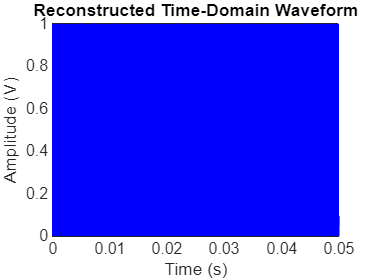

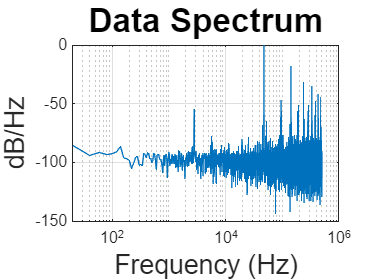

@Freq = 47485.350, SNR = 33.522 dB, SNDR = 17.642 dB, SFDR = 17.944 dB, HD2 = 46.338 and HD3 = 17.944


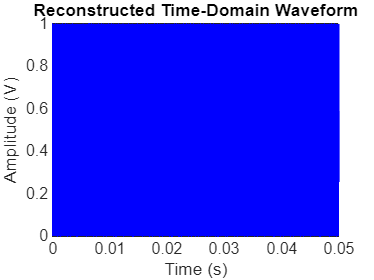

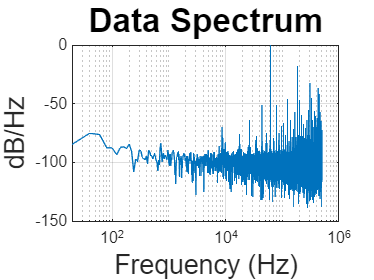

@Freq = 61401.370, SNR = 33.533 dB, SNDR = 17.642 dB, SFDR = 17.944 dB, HD2 = 46.073 and HD3 = 17.944


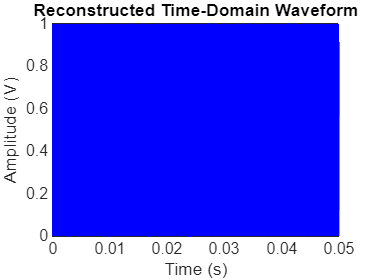

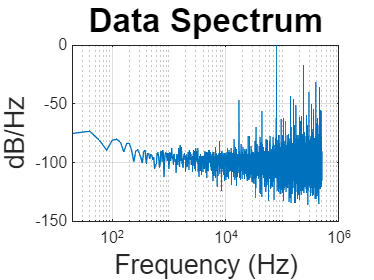

@Freq = 78247.070, SNR = 33.535 dB, SNDR = 17.644 dB, SFDR = 17.946 dB, HD2 = 46.170 and HD3 = 17.946


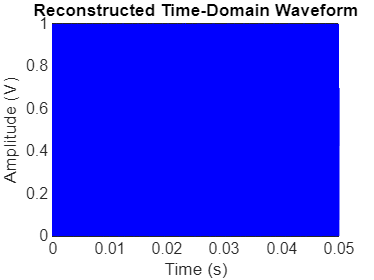

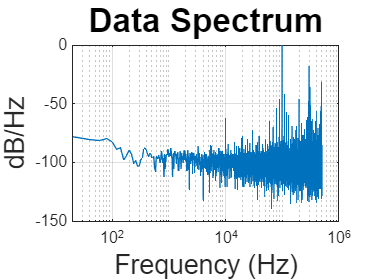

@Freq = 98999.020, SNR = 33.514 dB, SNDR = 17.641 dB, SFDR = 17.944 dB, HD2 = 46.320 and HD3 = 17.944


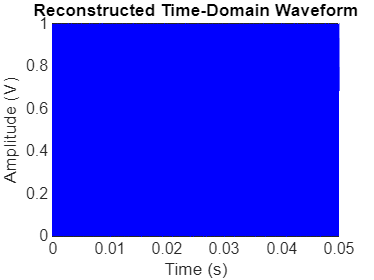

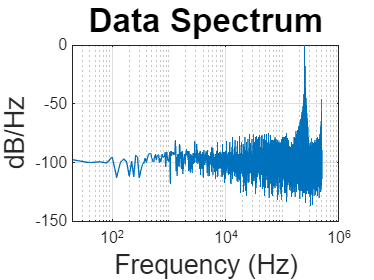

@Freq = 248901.370, SNR = 17.600 dB, SNDR = 17.580 dB, SFDR = 17.886 dB, HD2 = 46.304 and HD3 = 17.886


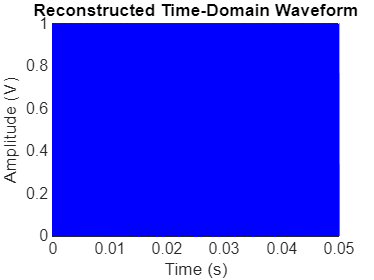

clearvars
freq_array = readtable('./ADC_Data/CML-Data/12-2-EthanTBBoard5_BYPASS-Freq_1k_250k-SIN_950mV-CLK_1MHz_Duty50%/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = round(freq_array,2);
%%% Remember to change this! if folder change
filepath = './ADC_Data/CML-Data/12-2-EthanTBBoard5_BYPASS-Freq_1k_250k-SIN_950mV-CLK_1MHz_Duty50%/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'Hz_.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == 1)+1;
    time_diff = diff(rising_edge_indices);
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 10));
    % data_NewDec = data_NewDec(1:5000);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=length(data_NewDec);
    % sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

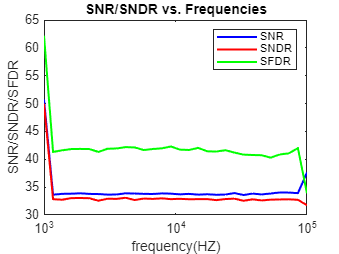

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

% Detect crossings: Where signal crosses 0.5
threshold = 512/2;
crossing_indices = find((data_NewDec(1:end-1) < threshold & data_NewDec(2:end) >= threshold) | ...
                        (data_NewDec(1:end-1) >= threshold & data_NewDec(2:end) < threshold));

% Count crossings
num_crossings = length(crossing_indices);

% Display result
fprintf('Number of crossings: %d\n', num_crossings);

Number of crossings: 46
